## The GSW cryptosystem  

clear all
folderPaths = genpath('GSWClass\');
addpath(folderPaths);

digits(100)          % increase precision
B = vpa(10);         % noise bound
N = 4;               % key dimension
q = vpa(10)^20;      % ciphertext space
setup = Setup(N,q,B);
sk = KeyGen(setup);

% LWE ciphertexts
s = vpa(10)^3;
x = 1.2345;
zx = Ecd(vpa(x),s,q);
ct_x = LWE(setup,zx,sk)

ct_x =   LWE_Ciphertext with properties:

    A: [3636976735609176448.0    44454492912698972962.0    32658090315612686716.0    28729423112964225240.0]
    b: 8289703977890433814.0
    N: 4
    q: 100000000000000000000.0


ct_x = ct_x+ct_x; % encrypted addition
a = vpa(2);
ct_x = ct_x*a;    % public multiplication
Dec(ct_x,sk)/s

$$ans = 4.936$$

% GSW ciphertexts
 y = vpa(4.5678);
zy = Ecd(y,s,q);
ct_x = LWE(setup,zx,sk);  % LWE encryption
ct_y = GSW(setup,zy,sk)   % GSW encryption

ct_y =   GSW_Ciphertext with properties:

    c: [100×5 sym]
    N: 4
    q: 100000000000000000000.0


ct_xy = ct_y*ct_x;
xy = Dcd(Dec(ct_xy,sk),s^2,q)

$$xy = 5.613978$$

Dcd(Dec(ct_y+ct_y,sk),s,q) % encrypted addition

$$ans = 9.138$$

Dcd(Dec(ct_y*a,sk),s,q)    % public multiplication

$$ans = 9.138$$

## Plaintext state feedback

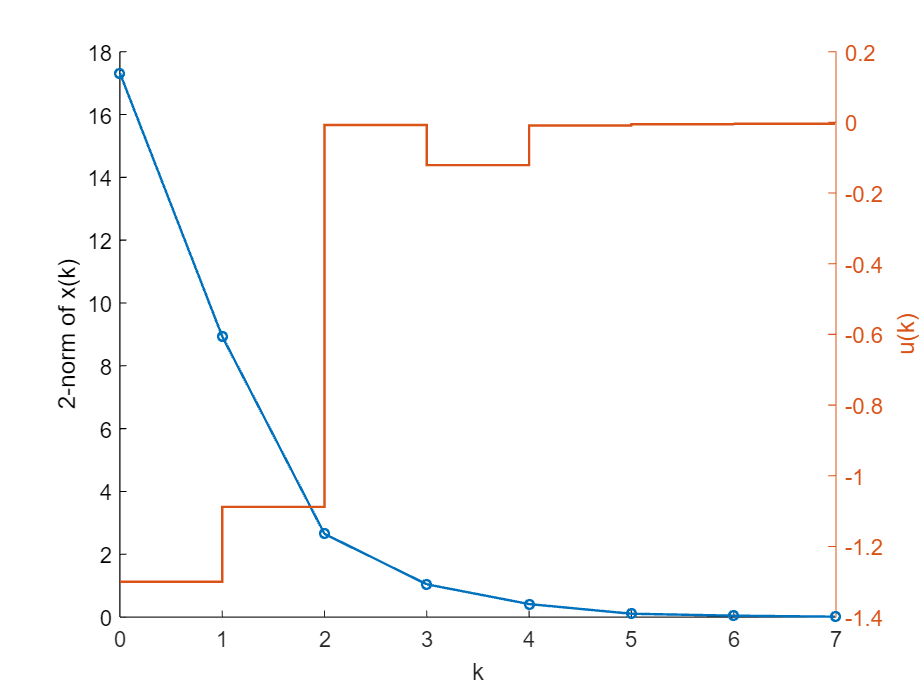

clear x
% system matrices
A = [-0.27  0.24  0.08; 
     -0.20 -0.35 -0.17;
      0.22 -0.02  0.36];
B = [-0.05; 0.11; 0.41];
C = [0 0 1.56];

% controller gain
K = [-0.07 0.06 -0.12];

% initalize
x(:,1) =[10; 10; 10];
kEnd = 8;

% main routine
for k = 1:kEnd
    u(k) = K*x(:,k);
    x(:,k+1) = A*x(:,k)+B*u(k);
end

% plot
figure
hold on
plot(0:kEnd-1,arrayfun(@(cols) norm(x(:,cols),2),1:kEnd),...
    'LineWidth',1.1,'Marker','o','MarkerSize',4)
xlabel('k')
ylabel('2-norm of x(k)')

yyaxis right
stairs(0:kEnd-1,u,'LineWidth',1.1)
ylabel('u(k)')

## Encrypted state feedback

% initialize 
 s = vpa(10)^3;
zx = Ecd(x(:,1),s,q);
zK = Ecd(K,s,q);
ct_K = GSW(setup,zK,sk);
ct_x = LWE(setup,zx,sk);

% main routine
for k = 1:kEnd
    if k == 1
        progressbar('Iteration:')      % initialize progressbar
    end
    progressbar(k/kEnd*100)            % update progressbar

    ct_u = ct_K*ct_x;                  % @ cloud
      zu = Dec(ct_u,sk);               % @ actuator
    u(k) = Dcd(zu,s^2,q);              % @ actuator
    x(:,k+1) = A*x(:,k)+B*u(k);        %   system
    zx(:,k+1) = Ecd(vpa(x(:,k+1)),s,q);% @ sensor
    ct_x = LWE(setup,zx(:,k+1),sk);    % @ sensor

    if k==kEnd
        progressbar('done')             % end progressbar
    end
end

Iteration:

100%    [..........]

done


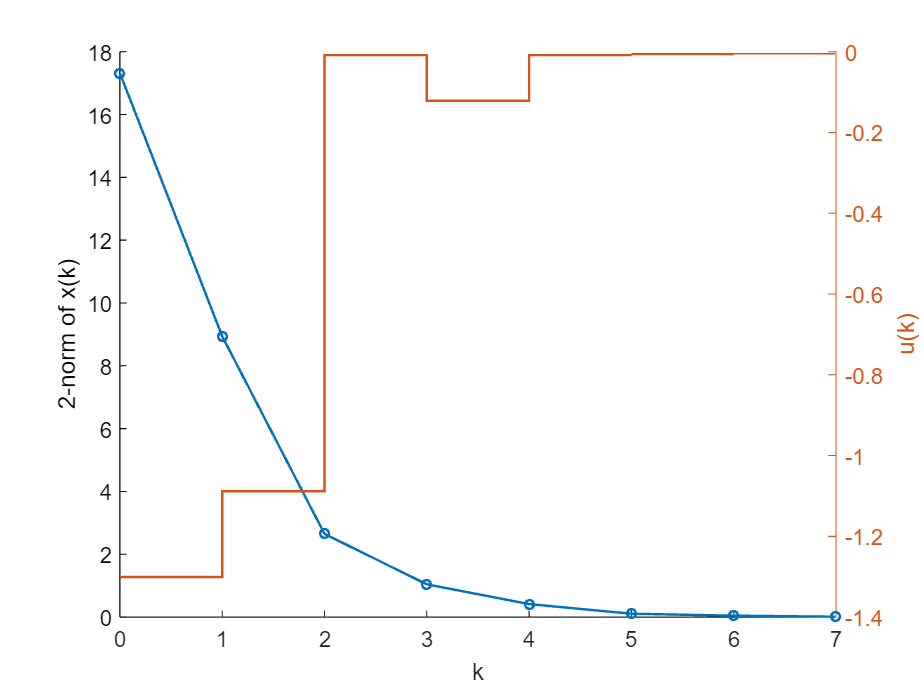

% plot
figure
hold on
plot(0:kEnd-1,arrayfun(@(cols) norm(x(:,cols),2),1:kEnd),...
    'LineWidth',1.1,'Marker','o','MarkerSize',4)
xlabel('k')
ylabel('2-norm of x(k)')

yyaxis right
stairs(0:kEnd-1,u,'LineWidth',1.1)
ylabel('u(k)')

## Plaintext PI control

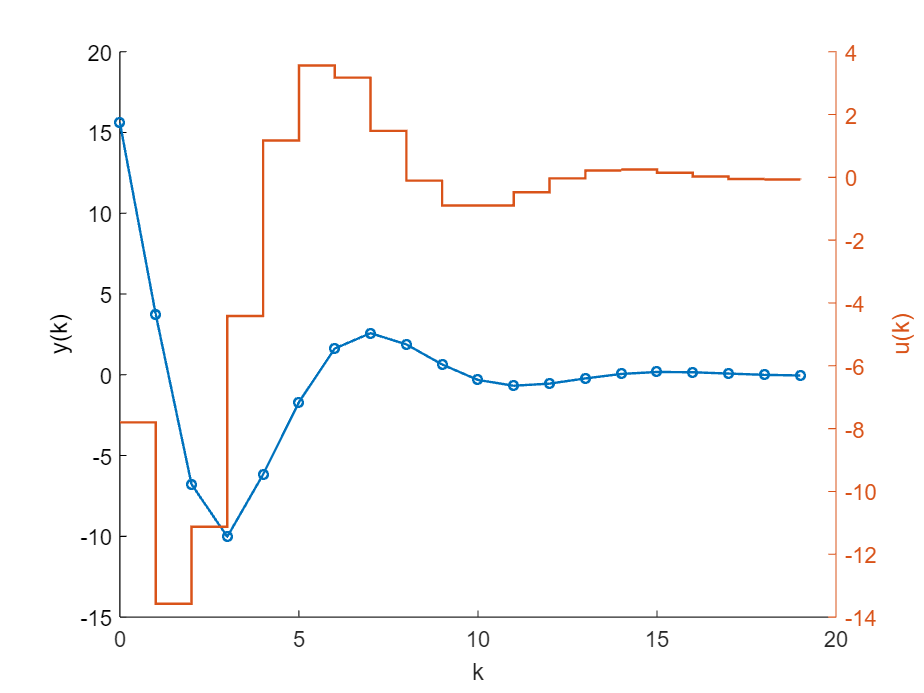

clear x

% controller parameters
dt = 1;
Ki = -0.75;
Kp = -0.5;
    
% initialize
xc = 0;
x(:,1) = [10; 10; 10];
kEnd = 20;

% main routine
for k = 1:kEnd
    y(k) = C*x(:,k);
    u(k) = Ki*xc(k)+Kp*y(k);
    xc(k+1) = xc(k)+dt*y(k);
    x(:,k+1) = A*x(:,k)+B*u(k);
end

% plot
figure
hold on
plot(0:kEnd-1,y,'LineWidth',1.1,'Marker','o','MarkerSize',4)
xlabel('k')
ylabel('y(k)')

yyaxis right
stairs(0:kEnd-1,u,'LineWidth',1.1)
ylabel('u(k)')

## Encrypted PI control

% initialize 
 s = vpa(10)^3;
zdt = Ecd(vpa(dt),s,q);
zKi = Ecd(vpa(Ki),s,q);
zKp = Ecd(vpa(Kp),s^2,q);
zxc = Ecd(xc(:,1),s^2,q);
ct_dt = GSW(setup,zdt,sk);
ct_Ki = GSW(setup,zKi,sk);
ct_Kp = GSW(setup,zKp,sk);
ct_xc = LWE(setup,zxc,sk);

% main routine
for k = 1:kEnd
    if k == 1
        progressbar('Iteration:')
    end
    progressbar(k/kEnd*100)
   
    y(k) = C*x(:,k);                %   system output
    zy = Ecd(vpa(y(k)),s,q);        % @ sensor
    ct_y = LWE(setup,zy,sk);        % @ sensor
    ct_u = ct_Ki*ct_xc+ct_Kp*ct_y;  % @ cloud
    ct_xc = ct_xc+ct_dt*ct_y;         % @ cloud
    zu = Dec(ct_u,sk);              % @ actuator
    u(k) = Dcd(zu,s^3,q);           % @ actuator
    x(:,k+1) = A*x(:,k)+B*u(k);     %   system state

    if k == kEnd
        progressbar('done')
    end
end

Iteration:


100%    [..........]

done


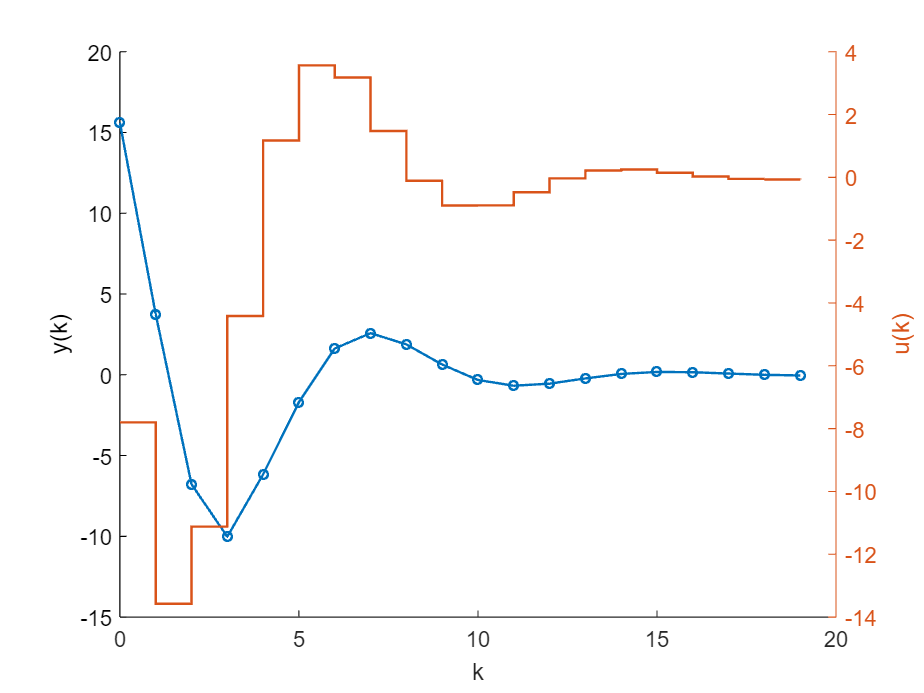

% plot
figure
hold on
plot(0:kEnd-1,y,'LineWidth',1.1,'Marker','o','MarkerSize',4)
xlabel('k')
ylabel('y(k)')

yyaxis right
stairs(0:kEnd-1,u,'LineWidth',1.1)
ylabel('u(k)')